# **二维标量场的梯度场演示**

**        对于二维标量函数，可以用gradient函数取梯度，从而得到一个矢量函数；此矢量函数可以用quiver 函数绘制箭头图；如果用contour函数再绘制该标量函数的等值线，还可以发现梯度和等值线是正交的。**

- **生成网格，沿着*****x*****、*****y*****方向分别在-2到2取25个点**

x=linspace(-2, 2, 25);       	
y=linspace(-2, 2, 25);       	
[xx, yy]=meshgrid(x, y);    	

- **定义一个二元函数**


$$z=a\;*\;{\mathrm{x}}^b +c{\;*\;\mathrm{y}}^d +e$$


a = 1;
b =2;
c = 1;
d =2;
e =1;
zz = a*xx.^b + c*yy.^d+e;    	%生成矩阵Z
fprintf('二元函数为z = %d*x^%d + %d*y^%d + %d\n', a, b, c, d, e);

二元函数为z = 1*x^2 + 1*y^2 + 1


- **使用contour函数计算等值线**

h=contour(xx,yy,zz, 4);        
clabel(h);                	    %写等高线的值

- **使用gradient函数求梯度**

[dx, dy]=gradient(zz,.2,.2);
hold on;                  	   

- **使用quiver绘制矢量图**

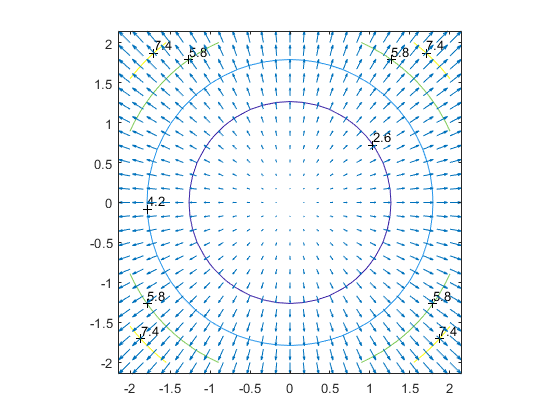

quiver(xx,yy,dx, dy);          
axis equal; 	    
set(gcf,'Visible','on');   	    %强制图片弹出显示
hold off;